I = imread(['./0.jpg']);
figure(1);
imshow(I);

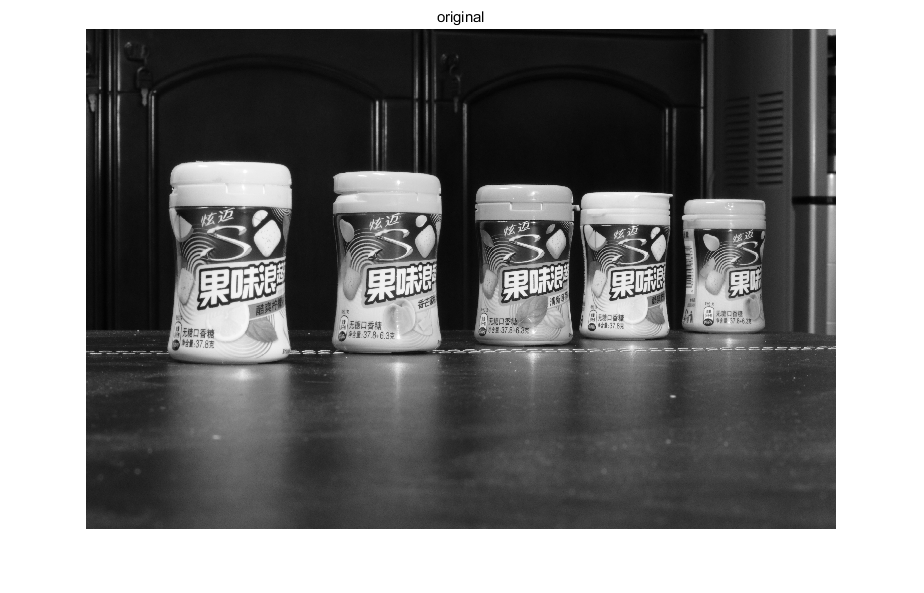

title("original");

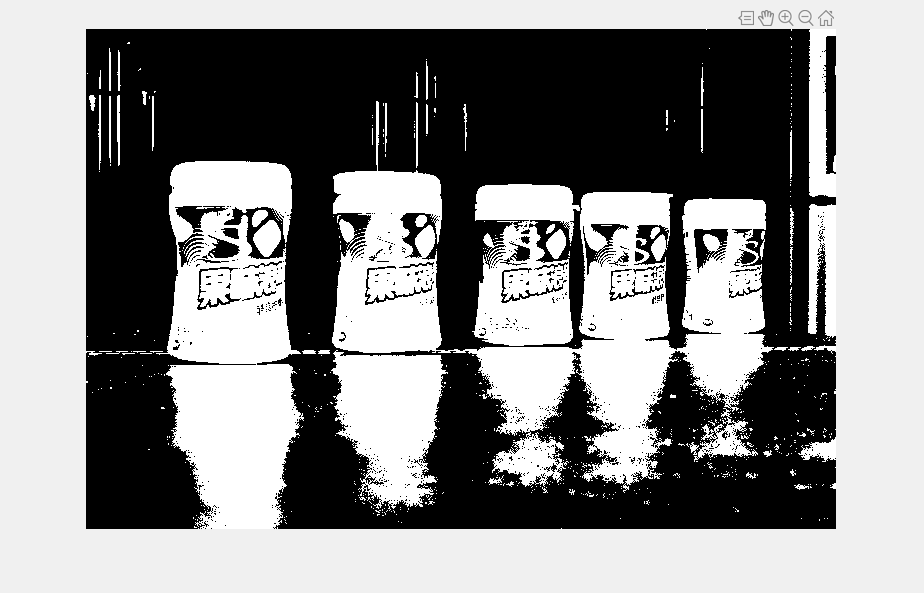

% 转换为二值图像，并手动选取区域
%biI=graythresh(I);
Ibw1 = imbinarize(I,mean2(I)/255.0);
[x, y, I2, rect] = imcrop(Ibw1);

rect=uint16(rect);

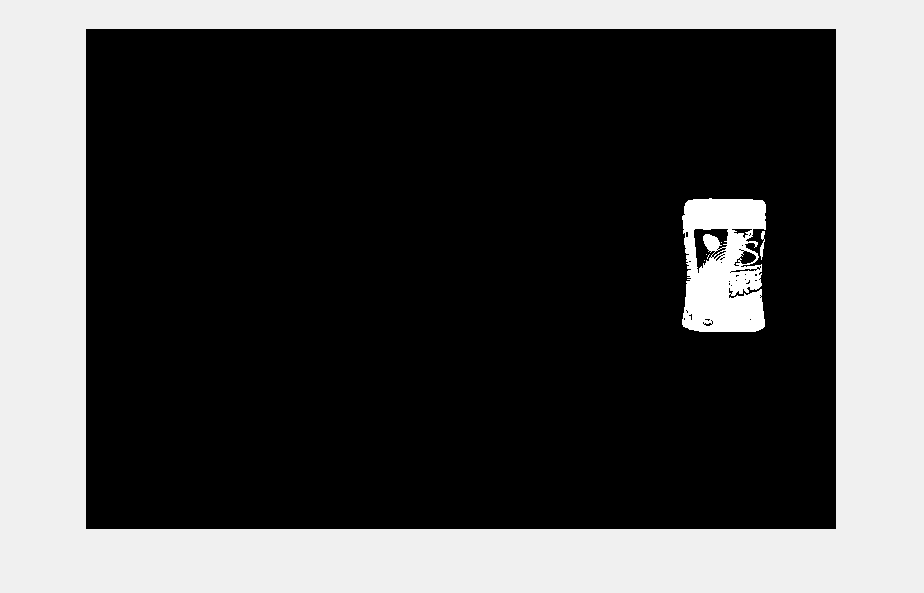

% 取出区域中的图像
mask=false(size(Ibw1));
mask(rect(2):rect(4)+rect(2), rect(1):rect(3)+rect(1))=true;
Ibw2=zeros(size(Ibw1));
Ibw2(mask)=Ibw1(mask);
imshow(Ibw2);

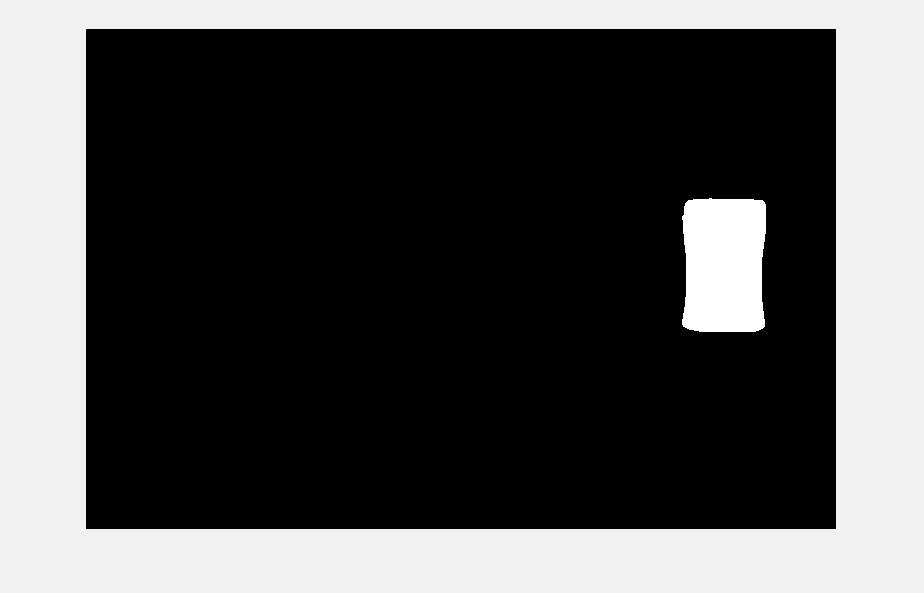

%对图像进行闭运算，得到封闭区域
se=strel('disk',80);
target = imclose(Ibw2, se);
imshow(target);

target=logical(target)

target = 4000×6000 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

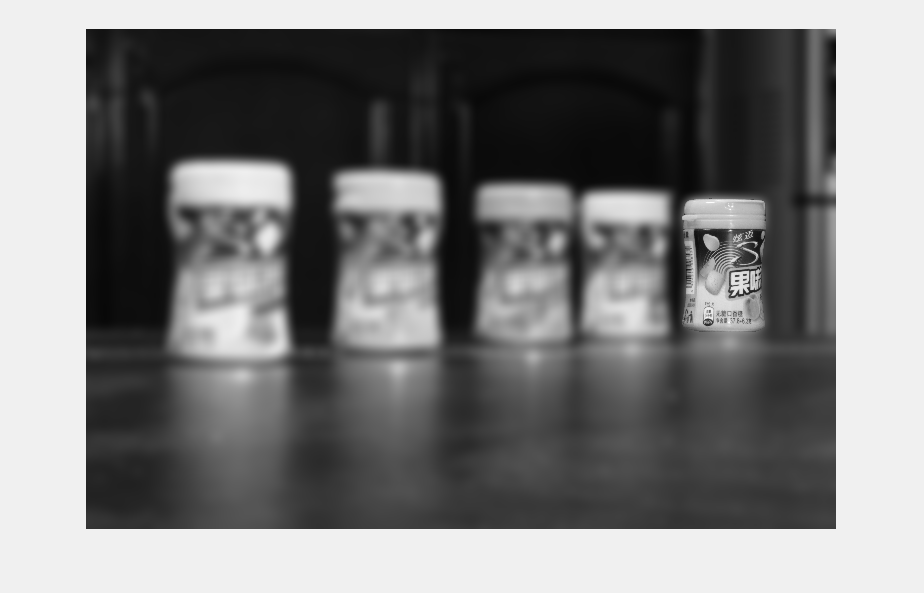

% 对图像作高斯模糊处理
Ig = imgaussfilt(I, 40);
% 选定区域用原图代替
Ig(target) = I(target);
imshow(Ig);

imwrite(Ig, "blur.jpg", "jpg");